# In this file i just want to review the data

clc;clear;
cd dataset\
load subj_1.mat
cd ..

whos 

  Name      Size                Bytes  Class    Attributes

  data      1x4             283853280  cell               



size(data{1})

ans =           64        7200          18


## so we have 64 channels not 63

### but is it same for all ? 

clc; clear;
cd dataset\
folder_path = '.'; 
num_subjects = 15;

for i = 1:num_subjects
    filename = fullfile(folder_path, sprintf('subj_%d.mat', i));
    if exist(filename, 'file')
        load(filename, 'data');
        
        [num_channels, num_samples, num_trials] = size(data{1});
        
        fprintf('Subject %2d: %d channels, %d samples, %d trials (class 1)\n', ...
            i, num_channels, num_samples, num_trials);
    else
        warning('File not found: %s', filename);
    end
end

Subject  1: 64 channels, 7200 samples, 18 trials (class 1)
Subject  2: 64 channels, 7200 samples, 20 trials (class 1)
Subject  3: 64 channels, 7200 samples, 19 trials (class 1)
Subject  4: 64 channels, 7200 samples, 19 trials (class 1)
Subject  5: 64 channels, 7200 samples, 20 trials (class 1)
Subject  6: 64 channels, 7200 samples, 20 trials (class 1)
Subject  7: 64 channels, 7200 samples, 17 trials (class 1)
Subject  8: 64 channels, 7200 samples, 20 trials (class 1)
Subject  9: 64 channels, 7200 samples, 19 trials (class 1)
Subject 10: 64 channels, 7200 samples, 19 trials (class 1)
Subject 11: 64 channels, 7200 samples, 19 trials (class 1)
Subject 12: 64 channels, 7200 samples, 18 trials (class 1)
Subject 13: 64 channels, 7200 samples, 20 trials (class 1)
Subject 14: 64 channels, 7200 samples, 20 trials (class 1)
Subject 15: 64 channels, 7200 samples, 19 trials (class 1)


cd ..

## so all of them are 64 channels

#### what about frequency spectrum?

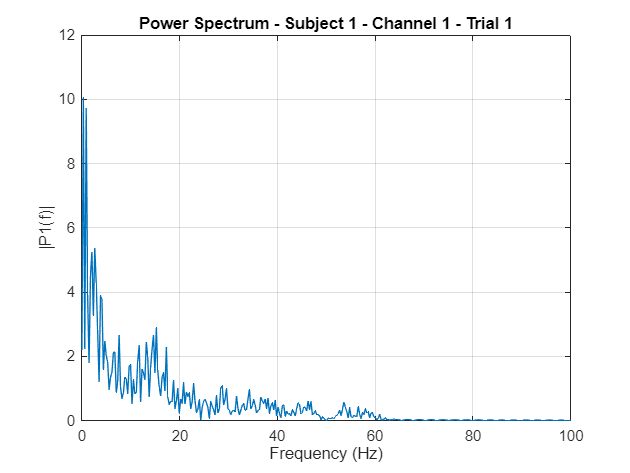

clc; clear;

subject_id = 1;
class_id = 1; % arm class 
channel_id = 1;  
trial_id = 1;
cd dataset\
load(sprintf('subj_%d.mat', subject_id));  

Fs = 2400;  % sampling frequency
signal = squeeze(data{class_id}(channel_id, :, trial_id));  

% FFT
L = length(signal);
NFFT = 2^nextpow2(L);
Y = fft(signal, NFFT);
P2 = abs(Y/L);     
P1 = P2(1:NFFT/2+1);   
P1(2:end-1) = 2*P1(2:end-1);  

f = Fs*(0:(NFFT/2))/NFFT;

figure;
plot(f, P1);
xlim([0 100]);  
xlabel('Frequency (Hz)');
ylabel('|P1(f)|');
title(sprintf('Power Spectrum - Subject %d - Channel %d - Trial %d', ...
    subject_id, channel_id, trial_id));
grid on;

## so this is low pass. but is it same for all channels ? 

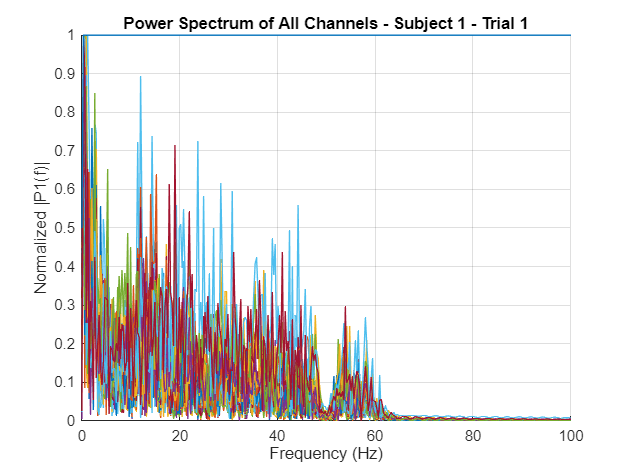

clc; clear;

subject_id = 1;
class_id = 1;  % arm class
trial_id = 1;
Fs = 2400; % sampling frequency

load(sprintf('subj_%d.mat', subject_id));
[num_channels, ~, ~] = size(data{class_id});

L = size(data{class_id}, 2);
NFFT = 2^nextpow2(L);
f = Fs*(0:(NFFT/2))/NFFT;

figure;
hold on;
for ch = 1:num_channels
    signal = squeeze(data{class_id}(ch, :, trial_id));
    Y = fft(signal, NFFT);
    P2 = abs(Y/L);
    P1 = P2(1:NFFT/2+1);
    P1(2:end-1) = 2*P1(2:end-1);

    P1 = P1 / max(P1); % Normalization: Just to better understand the diagram

    plot(f, P1);
end

xlim([0 100]);
xlabel('Frequency (Hz)');
ylabel('Normalized |P1(f)|');
title(sprintf('Power Spectrum of All Channels - Subject %d - Trial %d', subject_id, trial_id));
grid on;